# Linear Control Design 2 - Fall 2022 - Exam Part I - Solution Manual

## Introduction

The Part I of the Exam in Linear Control Design 2 (E22) consists of numerical exercises testing the acquisition of competences in the areas of analysis and design of control systems using modern control theory based on state space representation of system dynamics.

**The scoring of each problem is clearly stated.** 

It is the sole responsability of the student to guarantee that the solution delivered for evaluation can be run by the examiner without the need of contacting the student. All dependencies on files external to this Matlab Live Script must be checked and included in the final delivery. **If the examiner will not be able to execute the Matlab Live Script delivered as solution by the student, the Part I will be considered failed.** 

% Fill in your information
Exam = 'LCD2 E22'

Exam = 'LCD2 E22'

Student_Name = 'Student Name'

Student_Name = 'Student Name'

Student_Number = 'Student Number'

Student_Number = 'Student Number'

## Optimal output feedback control of a balance system

A balance system is a mechanical system in which the center of mass is balanced above a pivot point. A popular example of a balance system is the Segway Personal Transporter (shown in the figure below) where a motorized platform is used to stabilize the person standing on top of it. Balance systems are a generalization of a mass-spring-damper system to multi-degree-of-freedom, and the inverted pendulum on a cart (also shown in the figure below) is a good mechanical approximation of such systems.

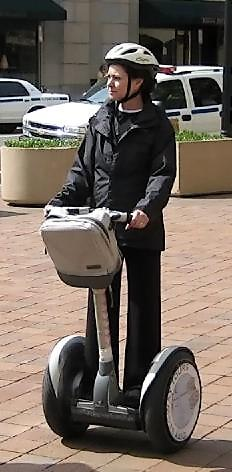            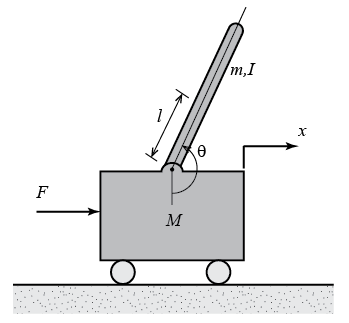

For this system the control input is the force $F$ that moves the cart in the longitudinal direction, and the measured output is the longitudinal position $x$ of the cart. The control objective is to keep the pendulum in its uprigth position ($\theta = \pi$rad) while moving the cart along the longitudinal direction. This is equivalent to the Segway Personal Transporter keeping its upright position while the rider leans forward to move along the ground. 

### Nonlinear model of the inverted pendulum on a cart

The nonlinear model describing the dynamical variations of the angular position of the pendulum $\theta$ and the linear position of the cart $x$ is described by the following nonlinear coupled second order differential equations

$(I + ml^2)\ddot{\theta} + c\dot{\theta} +mgl\sin\theta = -ml\ddot{x}\cos\theta  \\
(M+m)\ddot{x}+b\dot{x}+ml\ddot{\theta}\cos \theta-ml\dot{\theta}^2 \sin \theta = F$       (1)

where

- $M$is the mass of the cart

- $m$ is the mass of the pendulum

- $I$ is the inertia of the pendulum

- $b$ is the viscous friction coefficient of the cart

- $c$ is the viscous friction coefficient of the pendulum

- $l$ is the lenght of the pendulum

- $g$ is the gravitational constant 

The nonlinear model in Eq. (1) is implemented in the Simulink file InvertedPendulum_SimulinkYYYYC, where YYYYC refers to the Simulink version (2021b, 2021a, 2020b, 2020a, 2019b, 2019a, 2018b, 2018a, 2017b, 2017a). The numerical values for the model parameters are provided right below.

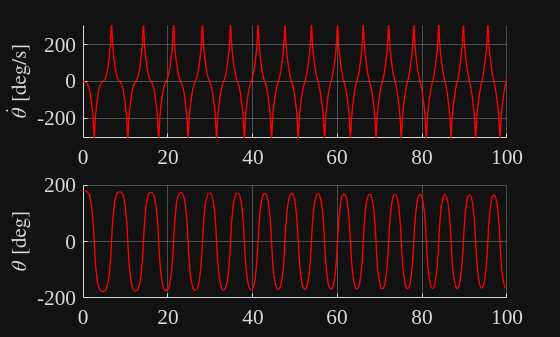

% Model paramters (RG)
% Prepare the workspace
clear all
clc
% System parameters
M = 10; % mass of trolley [kg]
m = 80; % mass of pendulum bob [kg]
b = 0.1; % friction coefficient trolley [kg/s]
c = 0.01; % friction coefficient pendulum [kg*m^2/s]
I = 100; % inertia of pendulum [kg*m^2]
g = 9.8; % gravity constant [m/s^2]
l = 1; % lenght of pendulum rod [m]

% Initial conditions for testing the Simulink model (RG)
theta_dot0 = 0; % pendulum angular velocity [rad/s]
theta0 = pi-0.01; % pendulum angular position [rad]
x_dot0 = 0; % trolley linear velocity [m/s]
x0 = 0; % trolley linear position [m]
F0 = 0; % linear force applied to the trolley [N]

% Test the provided inverted pendulum model (RG)
SIM_TIME = 100; % simulation time (can be changed as needed - if simulated for longer time, the pendulum returns to the downward position)
STEP_SIZE = 0.001; % integration step size of Simulink (can be changed as needed)
% Change with the name of the model you are using
SIMULINK_FILENAME = 'InvertedPendulum_Simulink2021b';
time = (0:STEP_SIZE:SIM_TIME)';
F_ctrl = F0*ones(length(time),1);
sim(SIMULINK_FILENAME,SIM_TIME,[],[time F_ctrl])

% Plot the temporal behaviour of the quantities of interest (RG)
theta_dot = rad2deg(logsout.getElement('theta_dot').Values.Data);
theta = wrapTo180(rad2deg(logsout.getElement('theta').Values.Data)); % the pendulum angular position is wrapped between -180 and 180 degress
x_dot = logsout.getElement('x_dot').Values.Data;
x = logsout.getElement('x').Values.Data;

figure, h1 = subplot(2,1,1); set(h1,'FontName','times','FontSize',16)
hold on, grid on
plot(time,theta_dot,'r','LineWidth',1)
ylabel('$\dot{\theta}$ [deg/s]','FontName','times','FontSize',16,'Interpreter','latex')
h2 = subplot(2,1,2); set(h2,'FontName','times','FontSize',16)
hold on, grid on
plot(time,theta,'r','LineWidth',1)
ylabel('$\theta$ [deg]','FontName','times','FontSize',16,'Interpreter','latex')

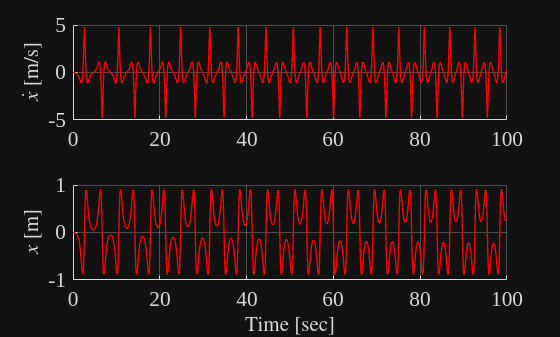

figure, h1 = subplot(2,1,1); set(h1,'FontName','times','FontSize',16)
hold on, grid on
plot(time,x_dot,'r','LineWidth',1)
ylabel('$\dot{x}$ [m/s]','FontName','times','FontSize',16,'Interpreter','latex')
h2 = subplot(2,1,2); set(h2,'FontName','times','FontSize',16)
hold on, grid on
plot(time,x,'r','LineWidth',1)
ylabel('$x$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')

### Open-loop system analysis

**Problem 1 [2 points]** Based on the system dynamics described in Eq. (1), determine the system state vector, input, disturbance and output. Exploiting the Simulink model InvertedPendulum_SimulinkYYYYC linearize the system about the following operating point: $\theta = \pi \, \mathrm{rad}; \, \dot{\theta}= 0\, \mathrm{rad/s}; \, x = 0\,\mathrm{m}; \, \dot{x} = 0\, \mathrm{m/s}$.

% Your solution goes here

xss = [0;pi;0;0]; % stationary state
yss = 0;
uss = 0;
[A,B,C,D] = linmod(SIMULINK_FILENAME,xss,uss);
B = B(:,1);
D = D(:,1);

disp('Linearized model @ xss = [0;pi;0;0]')

Linearized model @ xss = [0;pi;0;0]


disp('System dynamical matrix A')

System dynamical matrix A


display(A)

A =    -0.0001    7.2000   -0.0008         0
    1.0000         0         0         0
   -0.0001    6.4000   -0.0018         0
         0         0    1.0000         0


disp('System input matrix B')

System input matrix B


display(B)

B =     0.0082
         0
    0.0184
         0


disp('System output matrix C')

System output matrix C


display(C)

C =      0     0     0     1


disp('System input feedthrough matrix D')

System input feedthrough matrix D


display(D)

D = 0

**Problem 2 [2 points]** Evaluate the internal and the external stability of system.

% Your solution goes here
lambda_ol = eig(A)

lambda_ol =          0
    2.6829
   -2.6837
   -0.0011


disp('One eigenvalue has positive real part => System is unstable')

One eigenvalue has positive real part => System is unstable


[numG,denG] = ss2tf(A,B,C,D);

G_Fx = minreal(tf(numG,denG))


G_Fx =
 
     0.01837 s^2 + 1.02e-06 s - 0.08
  --------------------------------------
  s^4 + 0.001929 s^3 - 7.2 s^2 - 0.008 s
 
Continuous-time transfer function.
Model Properties


p = pole(G_Fx)

p =          0
   -2.6837
    2.6829
   -0.0011


disp('One pole has positive real part => System is not BIBO stable')

One pole has positive real part => System is not BIBO stable


**Problem 3 [2 points]** Compute the step response of the system, and discuss the behaviour of the system state and output in the light of the stability analysis.

% Your solution goes here
disp('When stepping on the input force the cart start moving with constant acceleration. Over time this will give rise to a change in position following a parabola (position is the second integration of acceleration).')

When stepping on the input force the cart start moving with constant acceleration. Over time this will give rise to a change in position following a parabola (position is the second integration of acceleration).


disp('In response to the step the pendulum position and velocity of the linear system will diverge to infinity because of the unstable eigenvalue. If the step is performed on the nonlinear system the response of the')

In response to the step the pendulum position and velocity of the linear system will diverge to infinity because of the unstable eigenvalue. If the step is performed on the nonlinear system the response of the


disp('cart position is exactly the same, however the pendulum will start swinging around its hinging point since its position is physically bounded between 0 and 2*pi.')

cart position is exactly the same, however the pendulum will start swinging around its hinging point since its position is physically bounded between 0 and 2*pi.


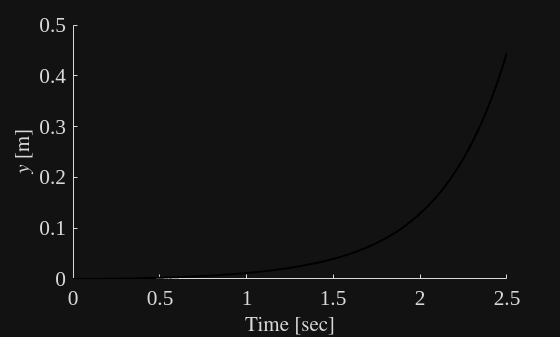


sys_ol = ss(A,B,C,D);
tFinal = 2.5;
[y,t,x] = step(sys_ol,tFinal);
figure, h5 = axes; set(h5,'FontName','times','FontSize',16)
hold on
plot(t,y,'k','LineWidth',1.5)
ylabel('$y$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')

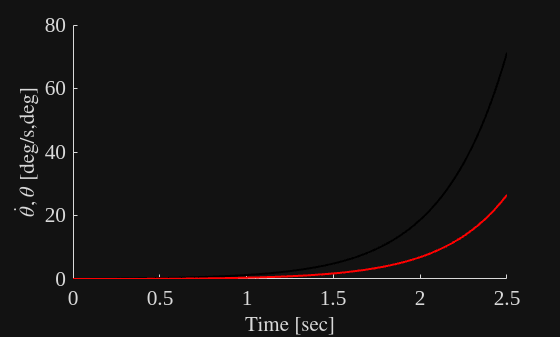

figure, h5 = axes; set(h5,'FontName','times','FontSize',16)
hold on
plot(t,rad2deg(x(:,1)),'k',t,rad2deg(x(:,2)),'r','LineWidth',1.5)
ylabel('$\dot{\theta},\theta$ [deg/s,deg]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')

### Control system design for balance system

The main control objective is to maintain the pendulum in its upright position while the cart changes its position along the longitudinal direction, e.g. following a trajectory $x_{ref}(t)$. 

Closed-loop system requirements

The following closed-loop requirements should be fulfilled when the position of the cart changes of 1m

- The 1% settling time for $x$ is between 25 and 35 seconds;

- The pendulum angular position $\theta$ does not deviate more than $\pi/48 \, \mathrm{rad}$ ($\approx 4 \, \mathrm{deg}$) from the upright position;

- The steady state error is less than 3% for $x$

- The applied control force $F$ is within $\pm10\,\mathrm{N}$

- The pendulum angular position is kept at $\theta_{ref} = \pi \, \mathrm{rad}$.

**Problem 4 [6 points]** Under the assumption that the state is fully accessible design a discrete time optimal controller that meets the aforementioned requirements.

% Your solution goes here

% Controllability test
Mc = ctrb(A,B);

if rank(Mc) == size(A,1)
    disp('Open loop linear system is controllable')
else
    disp('Open loop linear system is not controllable')
end

Open loop linear system is controllable


% Sampling time
T_sett = 25; % selected settling time [s]
tau_sett = T_sett/5; % slowest time constant of closed loop system [s]

tau_ol = 1./abs(lambda_ol(abs(lambda_ol)>0));
Ts_max = min([tau_sett min(tau_ol)]./10) % maximum sampling time [s]

Ts_max = 0.0373

Ts = 0.01; % sampling time [s]
[F,G] = c2d(A,B,Ts);

% Discrete time optimal controller
% Q = diag([0.1 0.1 1 5]); % state weighting matrix
Q = diag([100 1/(pi/48)^2 100 1/(0.03)^2]) % based on requirements on x (3% of error on 1m step change is 0.03m) and theta; weights on theta_dot and x_dot are selected to have a well damped response.

Q = 1.0e+03 *

    0.1000         0         0         0
         0    0.2334         0         0
         0         0    0.1000         0
         0         0         0    1.1111


R = 50; % input weighting matrix tuned to trade off between speed of response and use of control signal

[K_opt,S,lambda_cl_dt] = dlqr(F,G,Q*Ts,R*Ts);
lambda_cl_ct = 1/Ts.*log(lambda_cl_dt)

lambda_cl_ct =   -0.1624 + 0.1613i
  -0.1624 - 0.1613i
  -2.6804 + 0.0000i
  -2.6862 + 0.0000i


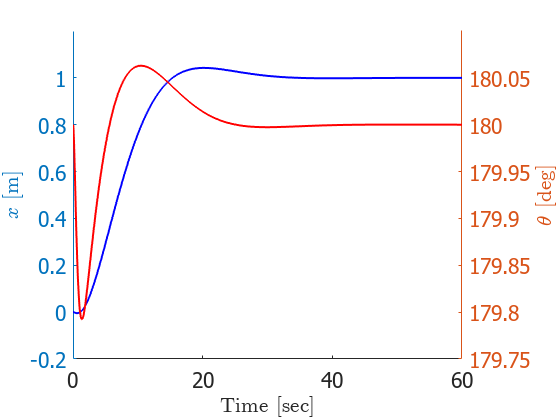

% Set-point control (a solution with integral action would also work here)
N = inv(C*inv(eye(4)-(F-G*K_opt))*G);
sys_cl_dt = ss(F-G*K_opt,G*N,C,D,Ts); % ver2: u = -K_LQR*x + Nr

% Simulate closed-loop step response
t_STEP = 10; % 10 seconds into the simulation
x_ref0 = 1;
x_ref = x_ref0*(ones(length(time(1:Ts/STEP_SIZE:end)),1));
ref = x_ref;
[y,t,x_lin] = lsim(sys_cl_dt,ref,time(1:Ts/STEP_SIZE:end));
% F_ctrl_lin = -K_opt*(x_lin'-ref);
F_ctrl_lin = -K_opt*x_lin' + N*x_ref';

figure, h6 = axes; set(h6,'FontName','times','FontSize',16)
hold on
yyaxis left
stairs(t,y,'b','LineWidth',1.5)
ylabel('$x$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
yyaxis right
stairs(t,rad2deg(x_lin(:,2)+pi),'r','LineWidth',1.5)
ylabel('$\theta$ [deg]','FontName','times','FontSize',16,'Interpreter','latex')
xlim([0,60])

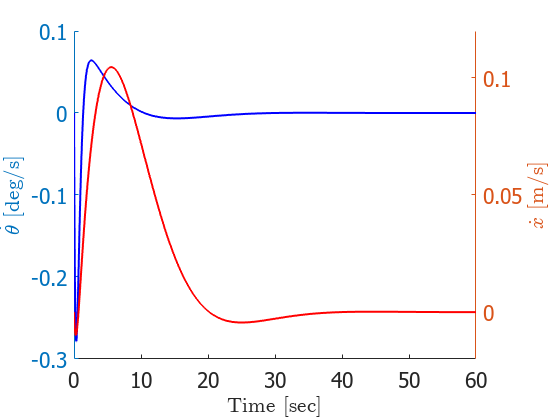

figure, h6 = axes; set(h6,'FontName','times','FontSize',16)
hold on
yyaxis left
stairs(t,rad2deg(x_lin(:,1)),'b','LineWidth',1.5)
ylabel('$\dot{\theta}$ [deg/s]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
yyaxis right
stairs(t,x_lin(:,3),'r','LineWidth',1.5)
ylabel('$\dot{x}$ [m/s]','FontName','times','FontSize',16,'Interpreter','latex')
xlim([0,60])

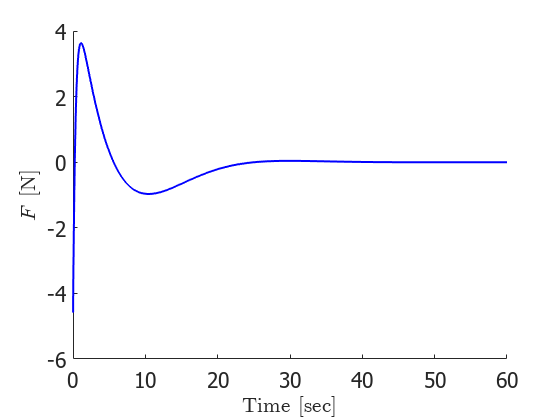

figure, h6 = axes; set(h6,'FontName','times','FontSize',16)
hold on
stairs(t,F_ctrl_lin,'b','LineWidth',1.5)
ylabel('$F$ [N]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')

**Problem 5 [2 points]** Implement the discrete time optimal controller in the Simulink model of the nonlinear system, and evalute the closed-loop system performance against the given requirements, when the sytem is subject to a step change in the reference trolley position of $x_{ref} = 0.5 \, \mathrm{m}$.

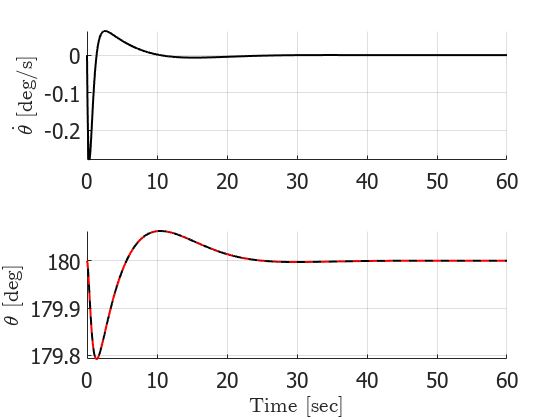

% Your solution goes here

% Test the closed-loop nonlinear system
SIM_TIME = 60; % simulation time (can be changed as needed)
STEP_SIZE = 0.001; % integration step size of Simulink (can be changed as needed)
% Change with the name of the model you are using
theta0 = pi;
SIMULINK_FILENAME = 'InvertedPendulum_DLQR_Simulink2020b';
sim(SIMULINK_FILENAME,SIM_TIME,[])

% Plot the temporal behaviour of the quantities of interest 
time = logsout.getElement('theta_dot').Values.Time;
theta_dot = rad2deg(logsout.getElement('theta_dot').Values.Data);
theta = rad2deg(logsout.getElement('theta').Values.Data); % the pendulum angular position is wrapped between -180 and 180 degress
x_dot = logsout.getElement('x_dot').Values.Data;
x = logsout.getElement('x').Values.Data;
time_dt = logsout.getElement('F').Values.Time;
F_ctrl = logsout.getElement('F').Values.Data;

figure, h7 = subplot(2,1,1); set(h7,'FontName','times','FontSize',16)
hold on, grid on
plot(time,theta_dot,'k','LineWidth',1.5)
ylabel('$\dot{\theta}$ [deg/s]','FontName','times','FontSize',16,'Interpreter','latex')
h8 = subplot(2,1,2); set(h8,'FontName','times','FontSize',16)
hold on, grid on
plot(time,theta,'k',t,rad2deg(x_lin(:,2)+pi),'--r','LineWidth',1.5)
ylabel('$\theta$ [deg]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')

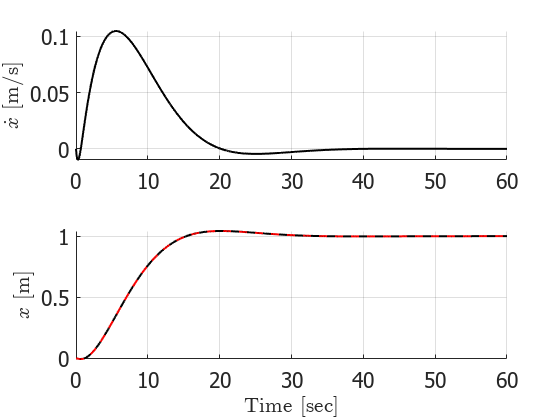

figure, h9 = subplot(2,1,1); set(h9,'FontName','times','FontSize',16)
hold on, grid on
plot(time,x_dot,'k','LineWidth',1.5)
ylabel('$\dot{x}$ [m/s]','FontName','times','FontSize',16,'Interpreter','latex')
h10 = subplot(2,1,2); set(h10,'FontName','times','FontSize',16)
hold on, grid on
plot(time,x,'k',t,x_lin(:,4),'--r','LineWidth',1.5)
ylabel('$x$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')

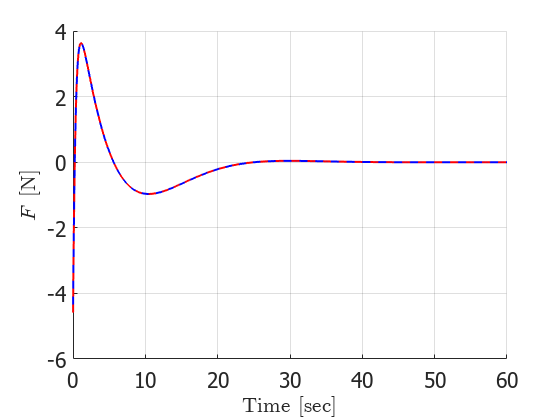

figure, h11 = axes; set(h11,'FontName','times','FontSize',16)
hold on, grid on
stairs(time_dt,F_ctrl,'b','LineWidth',1.5)
stairs(t,F_ctrl_lin,'--r','LineWidth',1.5)
ylabel('$F$ [N]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')

### State estimation for output feedback control

In order to implement an output feedback controller, the state vector must be estimated based on the available measurement of the cart position $x$. In the last part of the exercise, we assume the following measurement model

$y_1 = x + v_1$                            (2)

where $v_1$ is zero mean white noise. The noise amplitude is $\pm 0.005\, \mathrm{m}$. 

**Problem 6 [6 points]** Design a discrete time Kalman filter to estimate the state vector.

% Your solution goes here

% Observability test
Mo = obsv(A,C);

if rank(Mo) == size(A,1)
    disp('Open loop linear system is observable')
else
    disp('Open loop linear system is not observable')
end

Open loop linear system is observable


V1 = diag([0.00001 0.000001 0.00001 0.000001]); % process noise uncertainty is low across all states since the linear model is a good approximation of the nonlinear model at the stationary state
Bv = diag([A(1,1) 1 A(3,3) 1]); % process noise enters the system in the feedback loop of the states theta_dot and x_dot
V1d = Bv*V1*Bv'*Ts;
noise_ampl = 0.005;
V2 = (noise_ampl/3)^2;
V2d = V2/Ts;

F_KF = F;
G_KF = G;
Gv_KF = eye(4);
C_KF = C;

[L_KF,P,Z,lambda_ee_dt] = dlqe(F_KF,Gv_KF,C_KF,V1d,V2d)

L_KF =    202.1603e-003
    75.5765e-003
   179.5977e-003
    59.3151e-003


P =    229.2948e-006    86.1087e-006   203.6734e-006    59.6966e-006
    86.1087e-006    32.5263e-006    76.4873e-006    22.3172e-006
   203.6734e-006    76.4873e-006   180.9217e-006    53.0340e-006
    59.6966e-006    22.3172e-006    53.0340e-006    17.5153e-006


Z =    217.2265e-006    81.5971e-006   192.9520e-006    56.1556e-006
    81.5971e-006    30.8397e-006    72.4792e-006    20.9935e-006
   192.9520e-006    72.4792e-006   171.3969e-006    49.8883e-006
    56.1556e-006    20.9935e-006    49.8883e-006    16.4764e-006


lambda_ee_dt =    999.9558e-003
   991.6088e-003
   976.8052e-003
   971.1956e-003


x0_hat = zeros(4,1);

**Problem 7 [4 points]** Implement the discrete time Kalman filter in the Simulink diagram of the closed-loop system and assess its estimation performance when a step change in the position of the cart of $x_{ref} = 1 \, \mathrm{m}$ takes place.

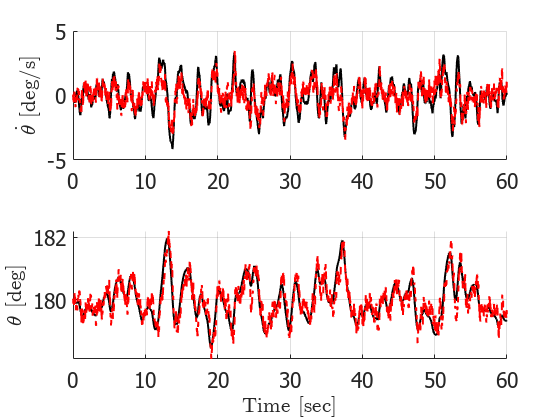

% Your solution goes here

% Test the closed-loop output feedback optimal controller on the nonlinear system
SIM_TIME = 60; % simulation time (can be changed as needed)
STEP_SIZE = 0.0001; % integration step size of Simulink (can be changed as needed)
% Change with the name of the model you are using
SIMULINK_FILENAME = 'InvertedPendulum_DLQG_Simulink2020b';
sim(SIMULINK_FILENAME,SIM_TIME,[])

% Plot the temporal behaviour of the quantities of interest 
time = logsout.getElement('theta_dot').Values.Time;
theta_dot = rad2deg(logsout.getElement('theta_dot').Values.Data);
theta = rad2deg(logsout.getElement('theta').Values.Data); % the pendulum angular position is wrapped between -180 and 180 degress
x_dot = logsout.getElement('x_dot').Values.Data;
x = logsout.getElement('x').Values.Data;
time_dt = logsout.getElement('F').Values.Time;
F_ctrl = logsout.getElement('F').Values.Data;
x_hat = logsout.getElement('x_hat').Values.Data+xss';
ym = logsout.getElement('ym').Values.Data;

figure, h12 = subplot(2,1,1); set(h12,'FontName','times','FontSize',16)
hold on, grid on
plot(time,theta_dot,'k','LineWidth',1.5)
stairs(time_dt,rad2deg(x_hat(:,1)),'--r','LineWidth',1.5)
ylabel('$\dot{\theta}$ [deg/s]','FontName','times','FontSize',16,'Interpreter','latex')
h13 = subplot(2,1,2); set(h13,'FontName','times','FontSize',16)
hold on, grid on
plot(time,theta,'k','LineWidth',1.5)
stairs(time_dt,rad2deg(x_hat(:,2)),'--r','LineWidth',1.5)
ylabel('$\theta$ [deg]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')

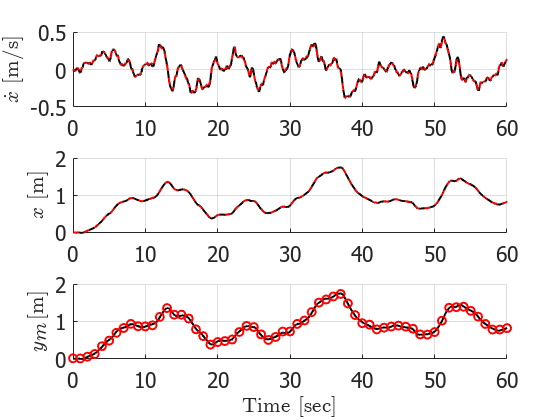

figure, h14 = subplot(3,1,1); set(h14,'FontName','times','FontSize',16)
hold on, grid on
plot(time,x_dot,'k','LineWidth',1.5)
stairs(time_dt,x_hat(:,3),'--r','LineWidth',1.5)
ylabel('$\dot{x}$ [m/s]','FontName','times','FontSize',16,'Interpreter','latex')
h15 = subplot(3,1,2); set(h15,'FontName','times','FontSize',16)
hold on, grid on
plot(time,x,'k','LineWidth',1.5)
stairs(time_dt,x_hat(:,4),'--r','LineWidth',1.5)
ylabel('$x$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
h16 = subplot(3,1,3); set(h16,'FontName','times','FontSize',16)
hold on, grid on
plot(time,x,'k','LineWidth',1.5)
plot(time_dt(1:100:end),ym(1:100:end),'or','LineWidth',1.5)
ylabel('$y_m$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')

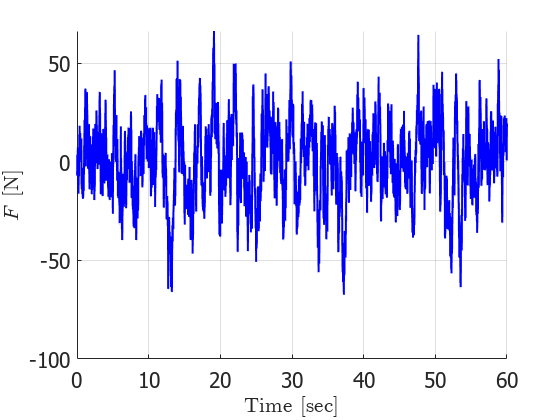

figure, h16 = axes; set(h16,'FontName','times','FontSize',16)
hold on, grid on
stairs(time_dt,F_ctrl,'b','LineWidth',1.5)
ylabel('$F$ [N]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')

disp('It is worth noticing that the introduction of measurement noise deteriorates the control performance in terms of control effort, which clearly exceeds the 10N given in the control design requirements.')

It is worth noticing that the introduction of measurement noise deteriorates the control performance in terms of control effort, which clearly exceeds the 10N given in the control design requirements.


disp('This may imply that give the level of sensor noise the requested control performance is too optimistic, and therefore relaxation of some requirements may be needed if the control signal should not exceed 10N.')

This may imply that give the level of sensor noise the requested control performance is too optimistic, and therefore relaxation of some requirements may be needed if the control signal should not exceed 10N.


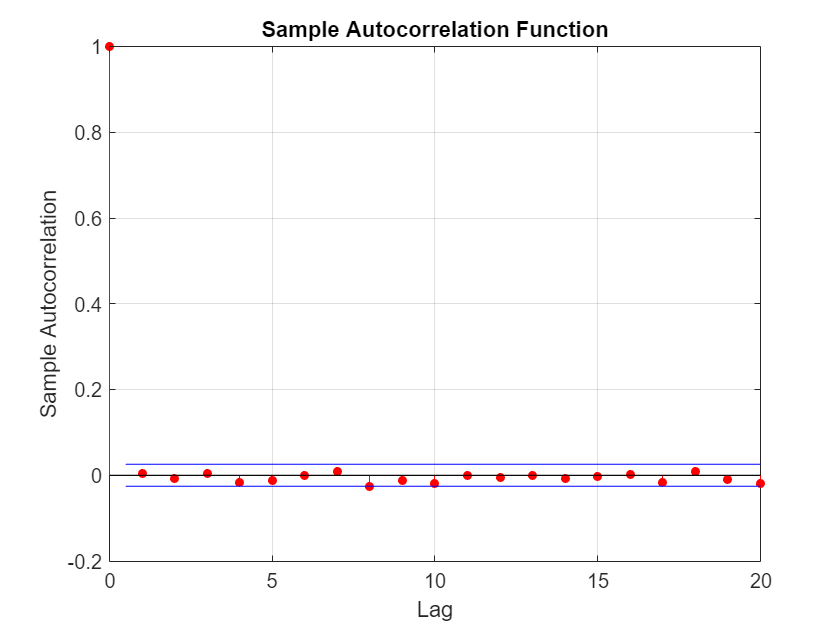


inno = ym-(C*x_hat')';
figure, autocorr(inno)

disp('The autocorrelation of the innovation signal clearly shows that the innovation is white noise, i.e. the Kalam filter is correctly estimating the state of the system')

The autocorrelation of the innovation signal clearly shows that the innovation is white noise, i.e. the Kalam filter is correctly estimating the state of the system



Q_sim = cov([deg2rad(theta_dot(1:100:end)) deg2rad(theta(1:100:end)) x_dot(1:100:end) x(1:100:end)]-x_hat) % estimation error covariance from simulation

Q_sim =    171.5128e-006    63.9758e-006   152.3577e-006    50.3426e-006
    63.9758e-006    23.8638e-006    56.8308e-006    18.7725e-006
   152.3577e-006    56.8308e-006   135.3419e-006    44.7237e-006
    50.3426e-006    18.7725e-006    44.7237e-006    15.7579e-006


display(Z) % estimation error covariance from Kalman filter design

Z =    217.2265e-006    81.5971e-006   192.9520e-006    56.1556e-006
    81.5971e-006    30.8397e-006    72.4792e-006    20.9935e-006
   192.9520e-006    72.4792e-006   171.3969e-006    49.8883e-006
    56.1556e-006    20.9935e-006    49.8883e-006    16.4764e-006


disp('The comparison of the theoretical and experimental estimation error covariance shows a very good agreement, reflecting that as long as the controller can keep the system')

The comparison of the theoretical and experimental estimation error covariance shows a very good agreement, reflecting that as long as the controller can keep the system


disp('close to the point of linearization the model utilized by the Kalman filter is a very good approximation of the linear system enabling an accurate estimate of the system state')

close to the point of linearization the model utilized by the Kalman filter is a very good approximation of the linear system enabling an accurate estimate of the system state
